clc, clearvars
% Motor Transfer Function
TF1 = tf(0.05,[1.0667e-6 3.3333e-4 0.079])

TF1 =
 
                 0.05
  -----------------------------------
  1.067e-06 s^2 + 0.0003333 s + 0.079
 
Continuous-time transfer function.
Model Properties



% Rotational speed to thrust 
A_t = 0.01309;

% Vehicle Equations of motion assuming that sin(theta) = 0 and cos(theta) =
% 1
TF2 = tf([0.002611 0.0121 0.01389], [1 5.178 10.18 7.66 -0.2063])

TF2 =
 
        0.002611 s^2 + 0.0121 s + 0.01389
  ---------------------------------------------
  s^4 + 5.178 s^3 + 10.18 s^2 + 7.66 s - 0.2063
 
Continuous-time transfer function.
Model Properties


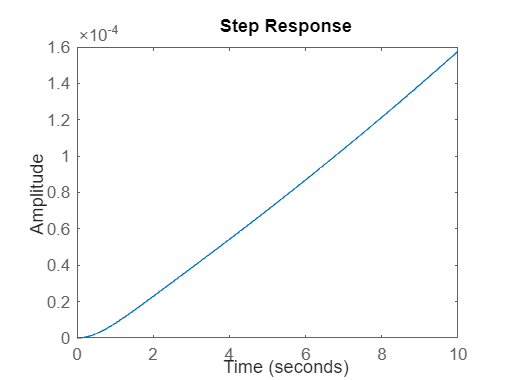


% Combined transfer function
TF_comb = TF1*A_t*TF2;

stepplot(TF_comb,10)

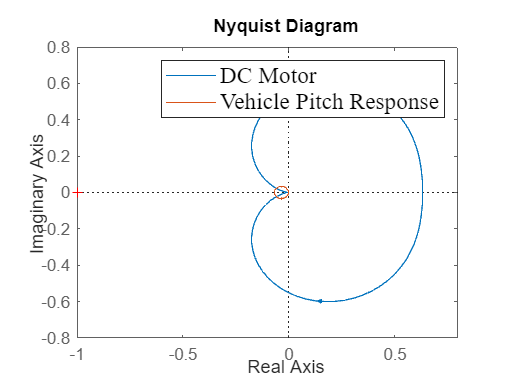


nyquistplot(TF1)
hold on 
nyquistplot(TF2)
legend("DC Motor", "Vehicle Pitch Response", fontname="Times New Roman", fontsize=14)
hold off

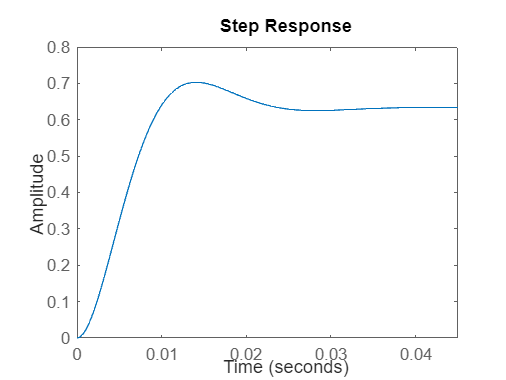


stepplot(TF1)

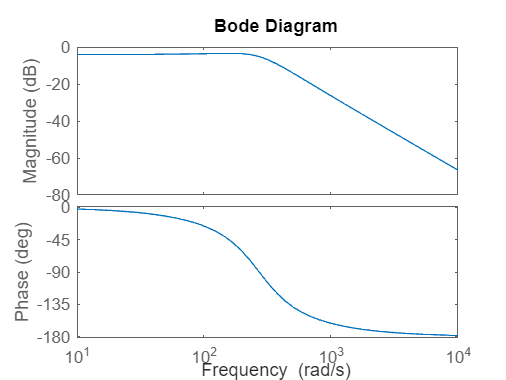

bode(TF1)

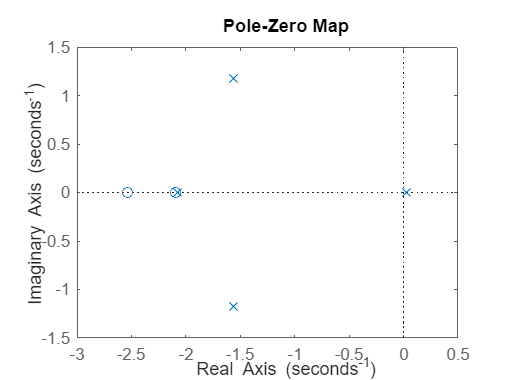


pzmap(TF2)